# Simulación de la respuesta de un sistema de un brazo robotico de dos grados de libertad a partir del MVE

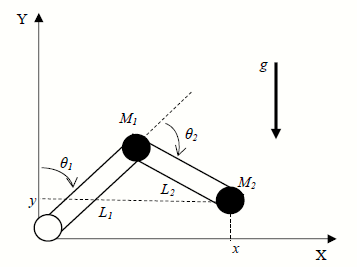

Considere que los parámetros del sistema son:

%Parámetros
g=9.81;
M1=1;
M2=1;
L1=1;
L2=1;
Theta1=pi*2;
Theta2=pi*2;
D1=(M1+M2)*(L1^2)+M2*(L2^2)+2*M2*L1*L2cos(Theta2);
D2=M2*L2^2+M2*L1*L2*cos(Theta2);
D3=D2;
D4=M2*L2^2;
M=(D1 D2;D3 D4);
G1=-(M1+M2)*g*L1*sin(Theta1)-M2*g*L2*sin(Theta1+Theta2);
G2=-M2*g*L2*sin(Theta1+Theta2);
C1=-M2*L1*L2*(2*Deltatheta1*Deltatheta2+Deltatheta1^2)*sin(Theta2);
C2=


Además las matrices del MVE obtenidas fueron:

%Matrices del MVE
A= [0 -(G1/M) 0 0;1 -(C1/M) 0 0;0 0 0 -(G2/M);0 0 1 -(C2/M)];
B= [];
C= [];
D= [0];

Utilizando el comando "**ss**" se puede generar el modelo dinámico del sistema a partir de las matrices del MVE:

sys = ss(A,B,C,D);

En este caso se desea conocer la respuesta del sistema (salida) cuando se aplica una entrada tipo escalón de magnitud 10 sin considerar condiciones iniciales.

Para ello se define primero las características de la señal de entrada:

opt = stepDataOptions('InputOffset',0,'StepAmplitude',16);

Y luego se definen los comandos para generar la respuesta, así como algunas configuraciones de la figura.

[y,t]=step(sys,opt);
u = 16*ones(length(t),1);
plot(t,u,'r',t,y,'g','LineWidth',1.5)
xlabel('tiempo (s)')
ylabel('amplitud (V)')
title('Respuesta del sistema ante entrada escalón de magnitud 16')
legend('entrada','salida')

Note que por el momento no se ha considerado el uso de condiciones iniciales. Para ello se puede hacer uso de la función "**lsim**".

Considere para el mismo ejemplo que en t = 0 s, las condiciones iniciales de los estados del sistema eran:

x0=[5 2];

y que se desea conocer la respuesta del sistema al aplicar una entrada escalón de magnitud 10 a partir de dicho instante inicial.

Se define el vector de tiempos de la simulación:

t2 = 0:0.001:0.1;

la entrada a aplicar al sistema:

u2 = 16*ones(length(t2),1);

y se realiza el llamado a la función:

[y2,t2]=lsim(sys,u2,t2,x0);

Finalmente se grafica la respuesta del sistema:

plot(t2,u2,'r',t2,y2,'g','LineWidth',1.5)
xlabel('tiempo (s)')
ylabel('amplitud (V)')
title('Respuesta del sistema ante entrada escalón de magnitud 16')
legend('entrada','salida')

